# **Exámen de Prácticas - Enero 2018**

**Introducción**

Necesitamos realizar la mezcla de tres grabaciones, las cuales emplearemos posteriormente en un sistema estéreo. El problema principal reside en que no todas ellas tienen la misma frecuencia de muestreo.  

#### **Problema 1 Interpolación**

Carga el fichero de sonido ‘pista_1.wav’ y realiza el procedimiento necesario para que su frecuencia de muestreo sea 22050 Hz. El resultado deberá almacenarse en el vector x1. 

NOTA: Ten en cuenta que no podrás emplear ninguna función de Matlab que realice este trabajo de forma automática.

Cuando interpolamos una señal lo que haremos será introducir un cero entre cada dos muestras, obteniendo algo así

a 0 b 0 c 0 d 0 e 0 f 0

Fs = 22050;
[x, fs] = audioread('pista_1.wav');

Necesitaremos saber la longitud del audio utilizado

Long_Sonido = length(x);

Obtenemos el índice de interpolado a partir de la frecuencia de muestreo que nos proporcionan

I = Fs/fs;

La longitud de la salida será el producto entre el indice de interpolado y la longitud del sonido original

Long_Sonido_Interp = Long_Sonido*I;

A continuación inicializamos la salida

X_Interpolada =zeros(Long_Sonido_Interp, 1);

Iniciaremos el bucle con el cual calcularemos y realizaremos la interpolación

for i = 1:Long_Sonido

Vamos a introducir un cero entre cada par de muestras

    X_Interpolada(i*I - 1) = x(i);
end

Diseñamos el filtro del interpolado

Calculamos su frecuencia de corte, que será la mitad de la frecuencia de muestreo

Fc = Fs/2;

Diseñamos el filtro, se tratará de un filtro paso bajo de tipo butter

[b, a] = butter(2, (Fc/Fs), 'low');

Para terminar, filtramos

X_Interpolada = filter(b, a, X_Interpolada);

Podemos comprobar si el resultado es correcto aprovechando la función que Matlab incorpora para la interpolación, necesitamos que sea de orden 2 para que añada un 0 por cada muestra, por lo que obtendremos el doble de muestras de las que teniamos

X_Interpolada_Matlab = interp(x,2);

Visualizando los resultados podemos comprobar si está realmente bien

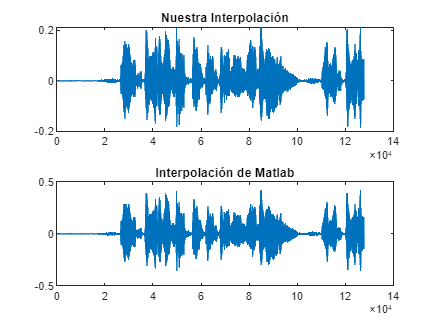

subplot(2,1,1)
plot(X_Interpolada)
title('Nuestra Interpolación')

subplot(2,1,2)
plot(X_Interpolada_Matlab)
title('Interpolación de Matlab')

#### **Problema 2 Diezmado**

Carga el fichero de sonido ‘pista_2.wav’ y realiza el procedimiento necesario para que su frecuencia de muestreo sea 22050 Hz. El resultado deberá almacenarse en el vector x2. NOTA: Ten en cuenta que no podrás emplear ninguna función de Matlab que realice este trabajo de forma automática.  

El diezmado de una señal se basa en eliminar parte de la información de la señal

Fs =22050;
[x, fs] = audioread('pista_2.wav');

Necesitaremos saber la longitud del audio utilizado

Long_Sonido = length(x);

Ahora diseñaremos el filtro para el diezmado de una señal

La frecuencia de corte será la mitad de la frecuencia de muestreo

Fc = Fs/2;

Diseñamos el filtro, se tratará de un filtro paso bajo de tipo butter

[b, a] = butter(2, Fc/Fs, 'low');

Obtenemos la salida del filtro

X_Diezmada_aux = filter(b, a, x);

Calculamos el índice de diezmado

D = Fs/fs;

La longitud del vector de salida

Long_Sonido_Diezmado = Long_Sonido/2;

Inicializamos la Salida

X_Diezmada = zeros(Long_Sonido_Diezmado, 1);

Generamos el bucle con el cuál eliminaremos una muestra de entre cada par de muestras

for i=1:Long_Sonido_Diezmado
    X_Diezmada(i) = X_Diezmada_aux(2*i-1);
end

Para comprobar si está bien hecho podemos comparar con el Diezmado que realiza Matlab, ponemos orden 2 para que elimine una muestra entre cada par de estas, por lo que obtendremos la mitad de muestras de las que teniamos en un principio

X_Diezmada_Matlab = decimate(x, 2);

Visualizando los resultados podemos comprobar si lo hemos hecho bien

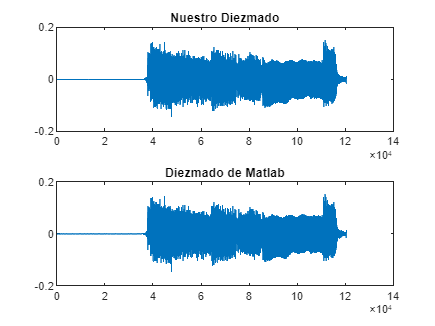

subplot(2,1,1)
plot(X_Diezmada)
title('Nuestro Diezmado')

subplot(2,1,2)
plot(X_Diezmada_Matlab)
title('Diezmado de Matlab')

#### Problema 3. Mezcla

Carga el fichero de sonido ‘pista_3.wav’ y almacénalo en el vector x3. Realiza el procedimiento necesario para mezclar x1, x2 y x3, en un único vector al que denominaremos y1.  

[x, fs] = audioread('pista_3.wav');

Necesitaremos la longitud de los 3 vectores, el de este ejercicio y los anteriores

Long_Sonido_Mezcla = length(x);

Long_Sonido_Interp = length(X_Interpolada);

Long_Sonido_Diezmado = length(X_Diezmada);

Vamos a necesitar obtener cual es la Longitud máxima para ajustar todos los vectores a esa longitud

LMax = max(Long_Sonido_Mezcla, Long_Sonido_Interp);
LMax = max(LMax, Long_Sonido_Diezmado);

El vector resultante deberá tener el tamaño de la señal más larga

Y = zeros(LMax, 1);

Rellenaremos con 0 para que todos tengan la misma duración

X_Mezcla = [x; zeros(LMax-Long_Sonido_Mezcla,1)];
X_Intepo = [X_Interpolada; zeros(LMax - Long_Sonido_Interp,1)];
X_Diezma = [X_Diezmada; zeros(LMax - Long_Sonido_Diezmado, 1)];

A continuación simplemente hacemos la mezcla de las tres señales

Y = X_Mezcla + X_Intepo + X_Diezma;

#### Problema 4 Panorámica

En este paso deseamos simular que la fuente se desplaza, comenzando en el altavoz izquierdo al principio de la grabación y terminando en el derecho al final. Determina y aplica la ganancia que debe emplearse en cada altavoz, para cada una de las muestras del vector y1. El resultado final debe ser una matriz con dos columnas, la primera se emitirá por el canal izquierdo y la segunda por el derecho. Ten en cuenta que la apertura de los altavoces está fijada a 60º, por tanto ∅ = 30°, y la imagen phantom debe estar obligatoriamente comprendida en el intervalo [-180º, 180º]. A continuación se muestran las ecuaciones de la ley de la tangente, y P=2. 

Primero obtendremos la longitud del vector utilizado, en este caso, el vector resultante del ejercicio 3

Long_Y = length(Y);

Obtendremos la trayectoria de la señal de la siguiente manera, siendo -30 y 30 los ángulos a los que puede llegar la señal y Long_Y lo larga que esta es. **Tal vez lo de -30 y 30 me lo he inventado**

Trayectoria = linspace(-30,30, Long_Y);

Inicializamos la variable TAU, que nos indicará el valor del ángulo

TAU = 30;

También inicializamos el vector de salida del problema

Y_Final = zeros(2, Long_Y);

A continuación crearemos un bucle dónde calcularemos las salidas

for i=1:length(Trayectoria)

Estas ecuaciones se han obtenido a papel a partir de despejar las dos ecuaciones vistas al principio

    K = tand(Trayectoria(i))/(tand(TAU));
    m = (1+K)/(1-K);
    GL = 1/(sqrt((m^2)+1));
    GR = m*GL;

Por cada muestra de la canción tendremos un ángulo y deberemos de cacular la ganancia para cada altavoz

Altavoz Izquierdo

    Y_Final(1,i) = Y(i)*GL;

Altavoz Derecho

    Y_Final(2,i) = Y(i)*GR;
end

Para reproducir el sonido resultante

sound(Y_Final, fs)

A continuación la visualización de los resultados para poder observar que hemos hecho

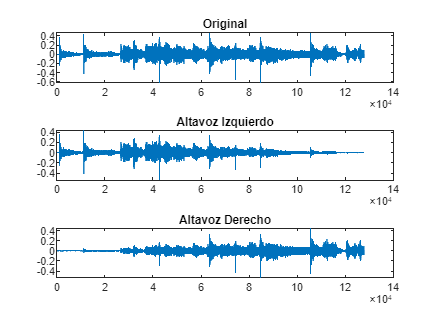

subplot(3,1,1)
plot(Y)
title('Original')

subplot(3,1,2)
plot(Y_Final(1,:))
title('Altavoz Izquierdo')

subplot(3,1,3)
plot(Y_Final(2,:))
title('Altavoz Derecho')